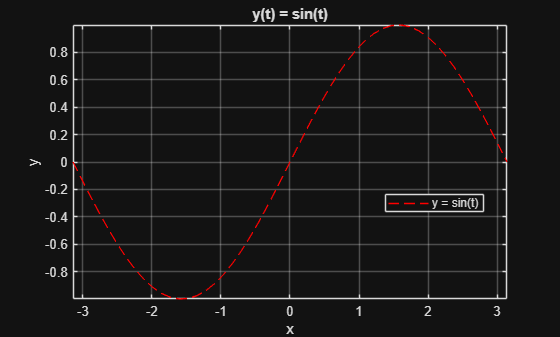


x = linspace(-pi, pi, 50);
y = sin(x);

figure(1); 
plot(x, y, 'r--'); 
title('y(t) = sin(t)'); 
xlabel('x'); 
ylabel('y'); 
axis([min(x) max(x) min(y) max(y)]); 
legend('y = sin(t)', 'Location', 'best'); 
grid on; 

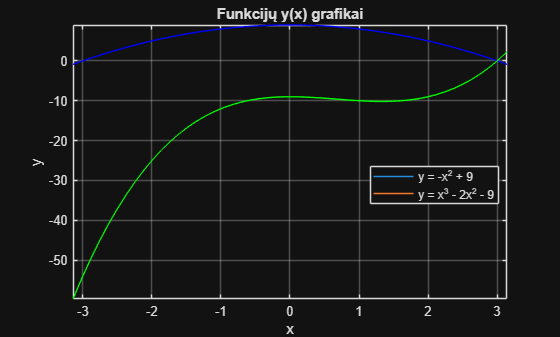

clear
x = linspace(-pi, pi, 50);
y1 = -x.^2 + 9;
y2 = x.^3 - 2*x.^2 - 9;

figure(2); 
plot(x, y1, 'b-', x, y2, 'g-');
title('Funkcijų y(x) grafikai'); 
xlabel('x');
ylabel('y');

y_min = min([min(y1), min(y2)]);
y_max = max([max(y1), max(y2)]);
axis([min(x) max(x) y_min y_max]);

legend('y = -x^2 + 9', 'y = x^3 - 2x^2 - 9', 'Location', 'best'); 

grid on;

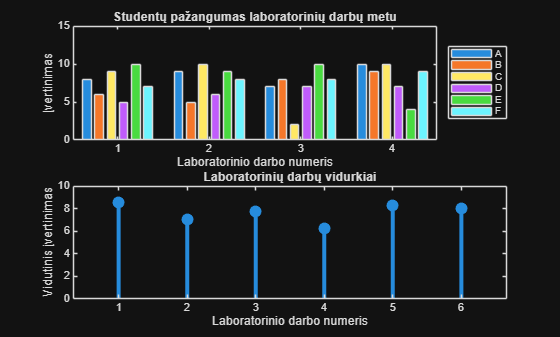

clear

pazymiai = [
    8, 9, 7, 10;
    6, 5, 8, 9;
    9, 10, 2, 10;
    5, 6, 7, 7;
    10, 9, 10, 4;
    7, 8, 8, 9
];

figure;

subplot(2, 1, 1);
bar(pazymiai',.7); 
title('Studentų pažangumas laboratorinių darbų metu');
xlabel('Laboratorinio darbo numeris'); 
ylabel('Įvertinimas'); 
ylim([0 15]);
legend('A', 'B', 'C', 'D', 'E', 'F', 'Location', 'eastoutside');

subplot(2, 1, 2);
vidurkiai = mean(pazymiai', 1);
stem(1:6, vidurkiai, 'filled', 'LineWidth', 3); 
title('Laboratorinių darbų vidurkiai'); 
xlabel('Laboratorinio darbo numeris');
ylabel('Vidutinis įvertinimas'); 
ylim([0 10]);

hold off

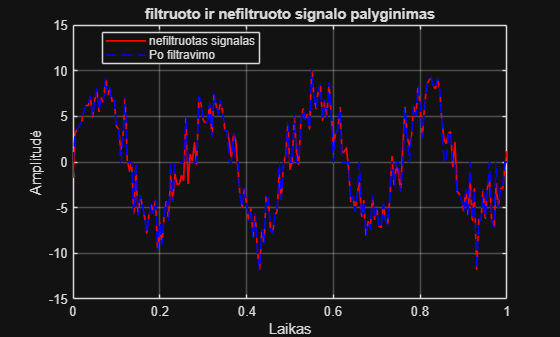

clear all
A = 7;
f = 4;
sigma = 2;
U_1 = 4.5;
U_2 = 2.5;
t = 0:0.005:1;

s = A*sin(2*pi*f*t);
n = sigma*randn(size(t));

s = s+n;

daugU_1 = s(s>U_1);

Fs = s;

Fs(abs(Fs) < U_2) = 0;

figure(1);
plot(t, s, 'r-', t, Fs, 'b--','linewidth',1.25);
title('filtruoto ir nefiltruoto signalo palyginimas');
xlabel('Laikas');
ylabel('Amplitudė');
legend('nefiltruotas signalas', 'Po filtravimo', 'Location', 'best');
grid on;

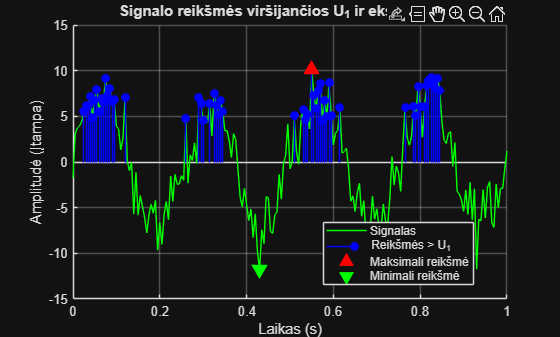


figure(4); 
clf; % Išvalo senus grafiko duomenis
hold on;

% Nubraižomas pagrindinis signalas
plot(t, s, 'g-', 'DisplayName', 'Signalas');

% Išrenkamos pradinio signalo reikšmės ir atitinkamas laikas, kurios viršija U_1 ribą
indeksai_virsija = s > U_1;
t_virsija = t(indeksai_virsija);
s_virsija = s(indeksai_virsija);

% Šios reikšmės pavaizduojamos diskrečiu formatu
stem(t_virsija, s_virsija, 'b', 'filled', 'DisplayName', 'Reikšmės > U_1');

% Surandamos minimalios ir maksimalios viso pradinio signalo įtampos reikšmės bei jų indeksai
[max_val, max_idx] = max(s);
[min_val, min_idx] = min(s);

% Minimalios ir maksimalios reikšmės grafike išryškinamos žymekliais (Marker)
plot(t(max_idx), max_val, 'r^', 'MarkerSize', 10, 'MarkerFaceColor', 'r', 'DisplayName', 'Maksimali reikšmė');
plot(t(min_idx), min_val, 'gv', 'MarkerSize', 10, 'MarkerFaceColor', 'g', 'DisplayName', 'Minimali reikšmė');

% Grafiko apipavidalinimas
title('Signalo reikšmės viršijančios U_1 ir ekstremumai');
xlabel('Laikas (s)');
ylabel('Amplitudė (Įtampa)');
legend('Location', 'best');
grid on;
hold off;